% Loading data
DrivFace = load("data/DrivFace/DrivFacec.mat"); % http://archive.ics.uci.edu/ml/datasets/DrivFace

DFdata = DrivFace.drivFaceD.data;
DFlabels = readtable("data/DrivFace/drivPoints.txt");

TCGA = csvread("data/TCGA-PANCAN-HiSeq-801x20531/data.csv", 1, 1); % http://archive.ics.uci.edu/ml/machine-learning-databases/00401/
TCGAdata = TCGA(:,1:5000); % Take a subset due to processor melting
TCGAlabels = readtable("data/TCGA-PANCAN-HiSeq-801x20531/labels.csv");

dissimilarities_DF = squareform(pdist(DFdata)); % compute dissimilarity matrix DFdata
dissimilarities_TCGA = squareform(pdist(TCGAdata)); % compute dissimilarity matrix DFdata

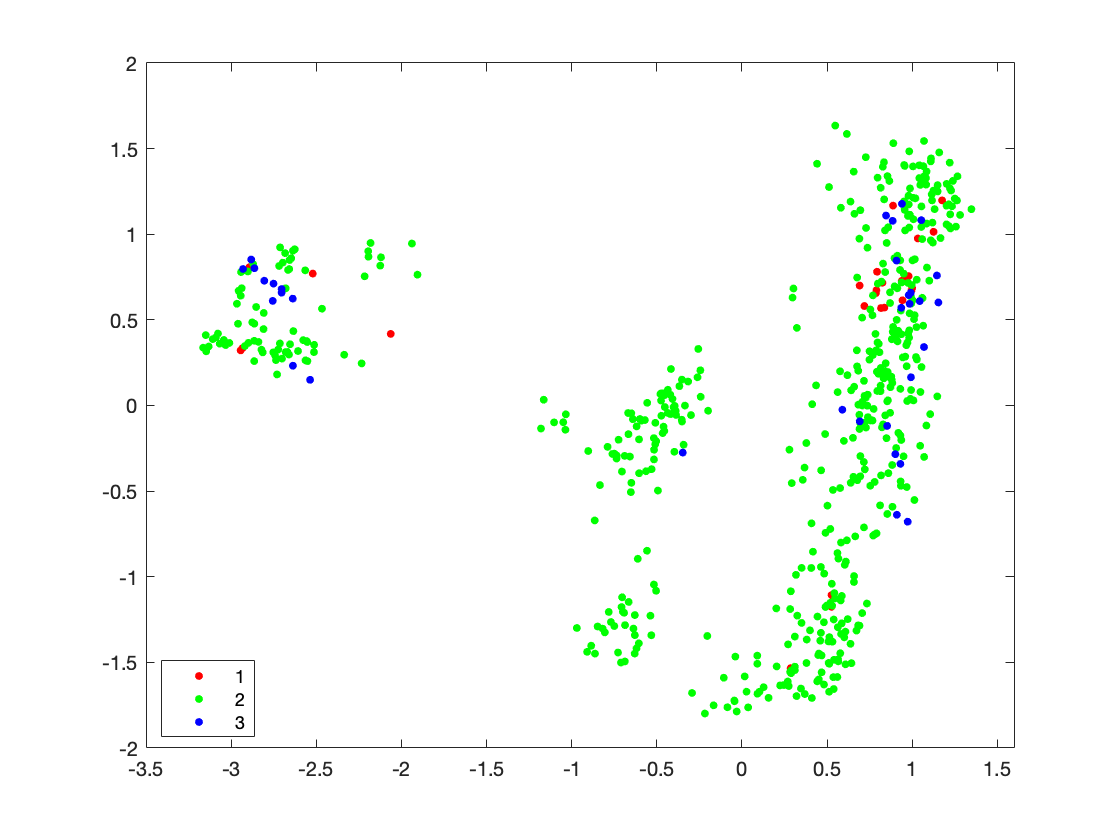

% Our implementation
% DF data
[Y,stress, lambda_p] = cmds(dissimilarities_DF,2); %Q: does not match matlab implementation
figure();
gscatter(Y(:,1),Y(:,2),DFlabels.label);

fprintf("Total stress s: %f", sum(stress(:))) %Q: this is very high

Total stress s: 107196402.841598

lambda_p

lambda_p =   978.6935         0
         0  487.0216


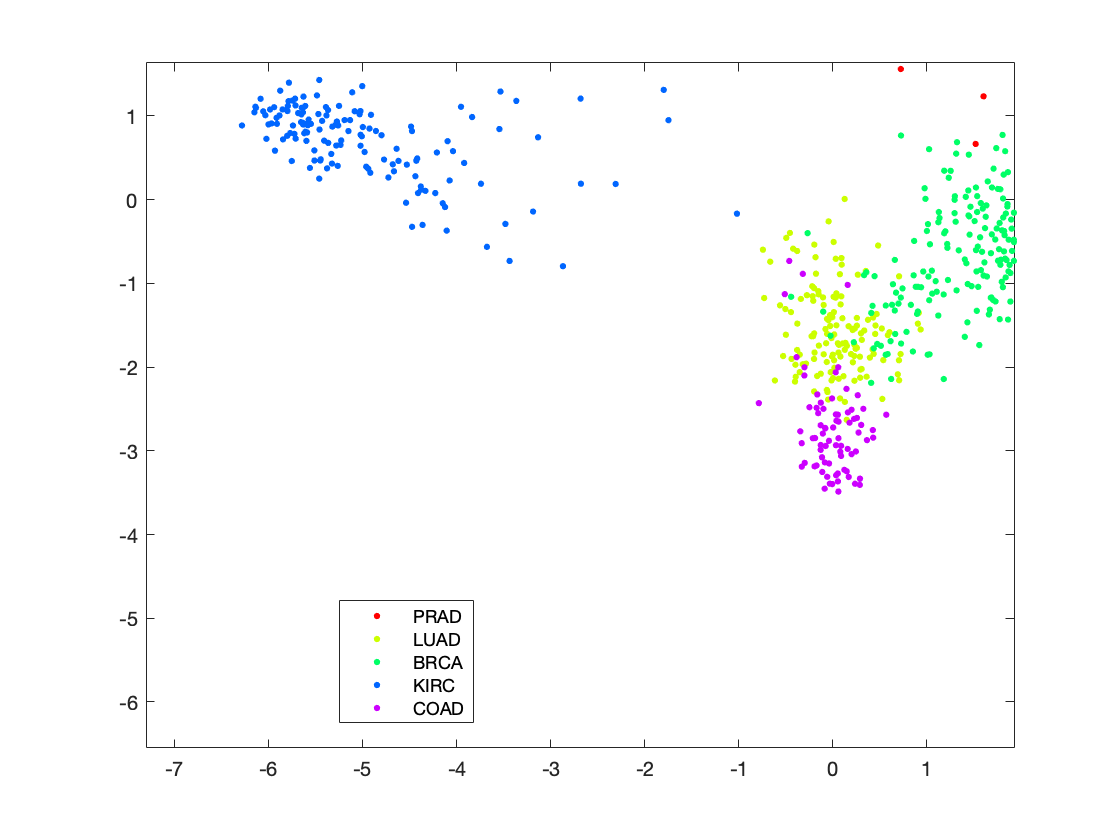


% TCGA data
[Y,stress, lambda_p] = cmds(dissimilarities_TCGA,2); %Q: does not match matlab implementation
figure();
gscatter(Y(:,1),Y(:,2), TCGAlabels.Class);

fprintf("Total stress s: %f", sum(stress(:))) %Q: this is very high

Total stress s: 11573450167.596640

lambda_p

lambda_p = 	1.0e+03 *

    5.1098         0
         0    3.3303


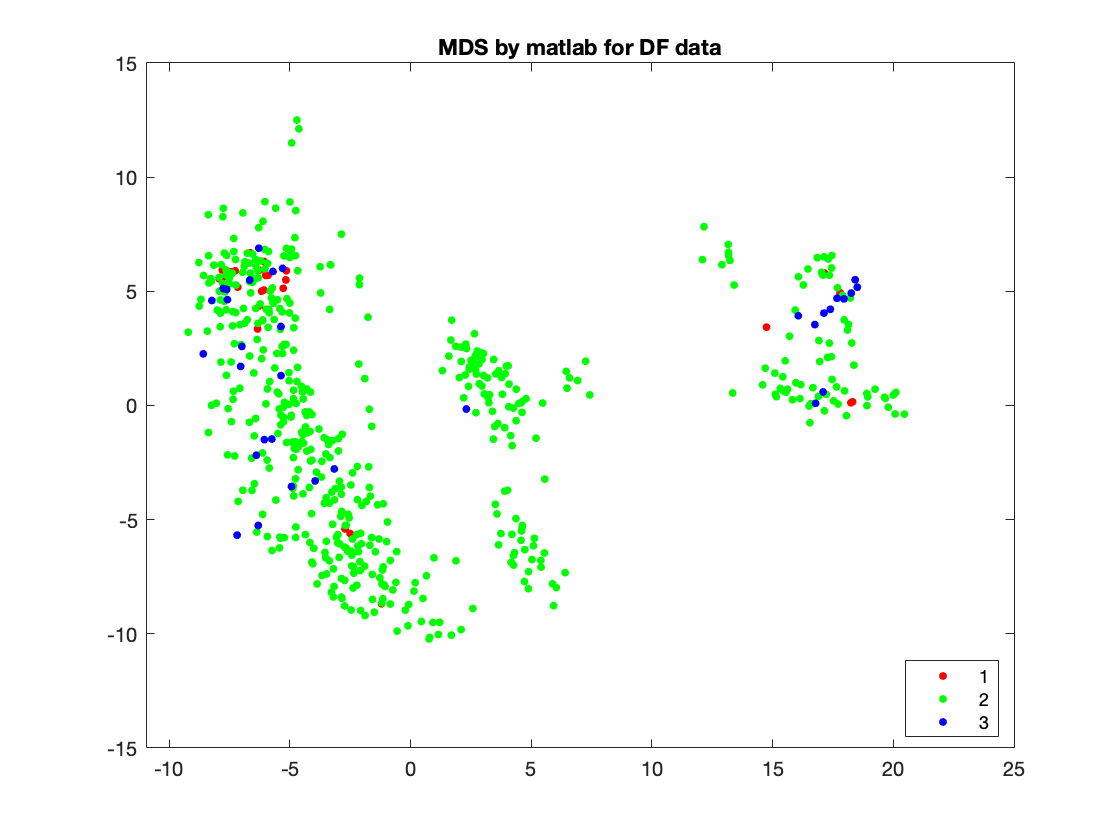

% Matlab implementation
% DF data
[Y,stress] = cmdscale(dissimilarities_DF,2); %Q: does not match matlab implementation
figure();
gscatter(Y(:,1),Y(:,2),DFlabels.label);
title('MDS by matlab for DF data');

fprintf("Total stress s: %f", sum(stress(:))) %Q: this is very high

Total stress s: 53181.717892

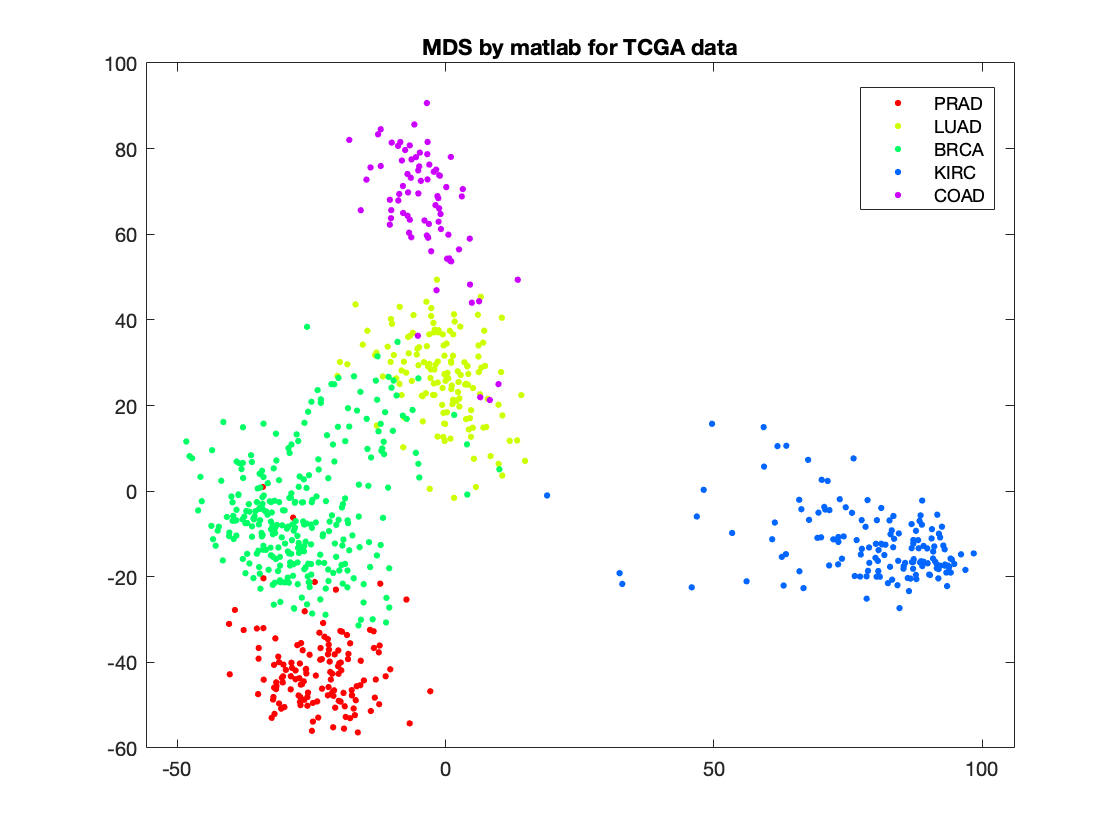


% TCGA data
[Y,stress] = cmdscale(dissimilarities_TCGA,2); %Q: does not match matlab implementation
figure();
gscatter(Y(:,1),Y(:,2), TCGAlabels.Class);
title('MDS by matlab for TCGA data');

fprintf("Total stress s: %f", sum(stress(:))) %Q: this is very high

Total stress s: 2106145.412520

function [Y, stress, lambda_p] = cmds(D, p)
    [n,m] = size(D);
    
    % Compute Gram matrix G using double centering
    In = eye(n); % N-by-n dentity matrix
    e = ones(n, 1); 
    part = In - (1/n) * (e * e.');
    G = -0.5 * part * D * part;
    
    % Compute eigenvalues (lambda) and vectors (u) of G Q: left or right?
    [u,lambda] = eig(G); 
    
    % Obtaining p highest eigenvalues and corresponding vectors
    [lambda_p, index_p] = maxk(diag(lambda), p);
    lambda_p = diag(lambda_p).';
    u_p = u(:,index_p);
    
    % For any d compute the coordinates of the points x_i
    Y = (u_p*sqrt(lambda_p));
    
    % Compute stress
    distances = squareform(pdist(Y));
    desired_distances = D;
    stress = (distances-desired_distances).^2; 
    
end
